**Xây dựng động học :**

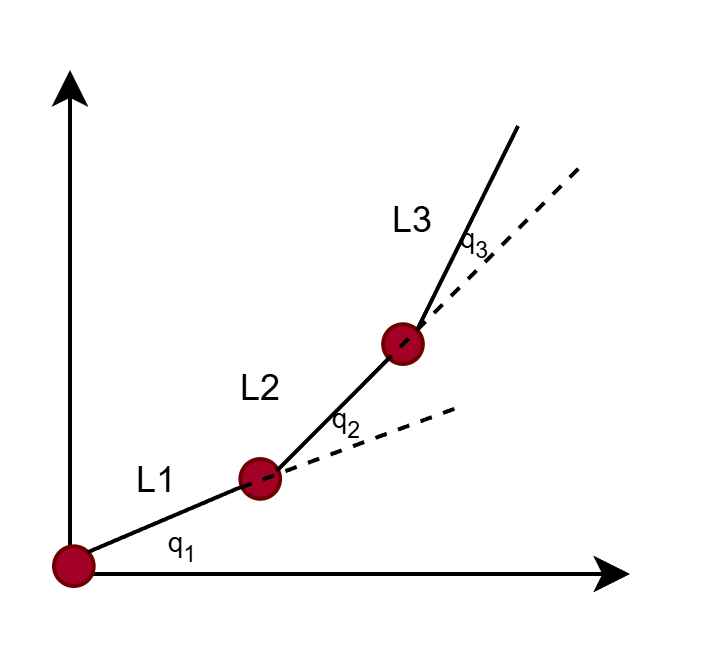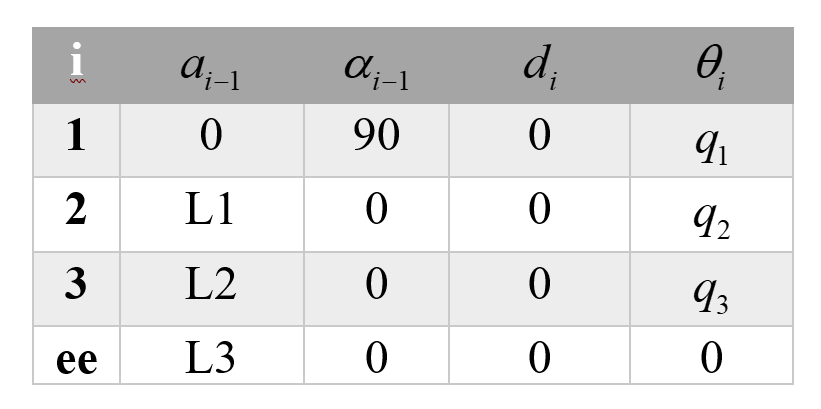

**Động học thuận:**

clear;clc;
syms q1 q2 q3 L1 L2 L3
T01=DH_modify(0,pi/2,0,q1);
T12=DH_modify(L1,0,0,q2);
T23=DH_modify(L2,0,0,q3);
T3EE=DH_modify(L3,0,0,0);
T0EE=simplify(T01*T12*T23*T3EE);
pee=T0EE(1:3,4);
Ree=T0EE(1:3,1:3);
%validationsyms q1 q2 q3 q4 q5 q6 

pee_test=double(subs(pee,[q1,q2,q3,L1,L2,L3],[pi/2 -pi/2 0 5 5 5]))

pee_test =    10.0000
    0.0000
    5.0000


Ree_test=double(subs(Ree,[q1,q2,q3,L1,L2,L3],[0 0 0 5 5 5]))

Ree_test =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


**Jacobian:**

J11=simplify(diff(pee(1,1),q1));
J12=simplify(diff(pee(1,1),q2));
J13=simplify(diff(pee(1,1),q3));

J21=simplify(diff(pee(2,1),q1));
J22=simplify(diff(pee(2,1),q2));
J23=simplify(diff(pee(2,1),q3));

J31=simplify(diff(pee(3,1),q1));
J32=simplify(diff(pee(3,1),q2));
J33=simplify(diff(pee(3,1),q3));

J41=simplify(T01(1,3));
J51=simplify(T01(2,3));
J61=simplify(T01(3,3));
T02=T01*T12;

J42=simplify(T02(1,3));
J52=simplify(T02(2,3));
J62=simplify(T02(3,3));

T0EE=T01*T12*T23*T3EE;

J43=simplify(T0EE(1,3));
J53=simplify(T0EE(2,3));
J63=simplify(T0EE(3,3));

J=[J11,J12,J13;
    J21,J22,J23;
    J31,J32,J33;
    J41,J42,J43;
    J51,J52,J53;
    J61,J62,J63;]

$$J = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{5}-L_{1}\,\sin\left(q_{1}\right)-\sigma_{2} & -\sigma_{5}-\sigma_{2} & -\sigma_{2}\\ \sigma_{4}+\frac{4967757600021511\,L_{1}\,\cos\left(q_{1}\right)}{81129638414606681695789005144064}+\sigma_{1} & \sigma_{4}+\sigma_{1} & \sigma_{1}\\ \sigma_{6}+L_{1}\,\cos\left(q_{1}\right)+\sigma_{3} & \sigma_{6}+\sigma_{3} & \sigma_{3}\\ 0 & 0 & 0\\ -1 & -1 & -1\\ \frac{4967757600021511}{81129638414606681695789005144064} & \frac{4967757600021511}{81129638414606681695789005144064} & \frac{4967757600021511}{81129638414606681695789005144064} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{4967757600021511\,L_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)}{81129638414606681695789005144064}\\ \sigma_{2}=L_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{3}=L_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\frac{4967757600021511\,L_{2}\,\cos\left(q_{1}+q_{2}\right)}{81129638414606681695789005144064}\\ \sigma_{5}=L_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{6}=L_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}$$

**Bảng DH:**

function T = DH_modify(a,alpha,d,theta)
%theta, alpha đơn vị radian
T = [cos(theta),-sin(theta),0,a ;
   sin(theta)*cos(alpha),cos(theta)*cos(alpha),-sin(alpha),-sin(alpha)*d;
   sin(theta)*sin(alpha),cos(theta)*sin(alpha),cos(alpha),cos(alpha)*d ;
   0,0,0,1];
end